# 7A_fractured sample analysis

% clearvars;
% navigate to the correct directory 
if exist('goto','file')
    goto(3); % this is my way of going to the project file
end

sevenAFracturedImageFileName = 'sevenA_fractured_image.mat';
sevenAFracturedImageFilePath = fullfile('prototyping','7A_fractured',sevenAFracturedImageFileName);

% loading the data
dataWasNotSaved = false; % this assumes data was already saved previously
if dataWasNotSaved
    data = loadImageSeq(fullfile('..','..','data','Bland','7A_fractured','8bitJPG'),'jpg');
    save(sevenAFracturedImageFilePath,'data','-v7.3','-mat');
else
    disp('loading from variable directly ...');
    load(sevenAFracturedImageFilePath);
    disp('loading completed');
end

loading from variable directly ...


loading completed


Inspecting the volume visually, we can identify the range of indices that we will use in generating the adequate subvolume for the analysis. 

figure
osv = orthosliceViewer(data.image,'DisplayRange',[5 65],'DisplayRangeInteraction',"off");

By visual inspection, the following values have been determined to be the min and max indices for each dimention

xmin = 330; xmax = 500; % xmax was 510, changed 500 because of an anomoly 
ymin = 50;  ymax = 750;
zmin = 50;  zmax = 1860;

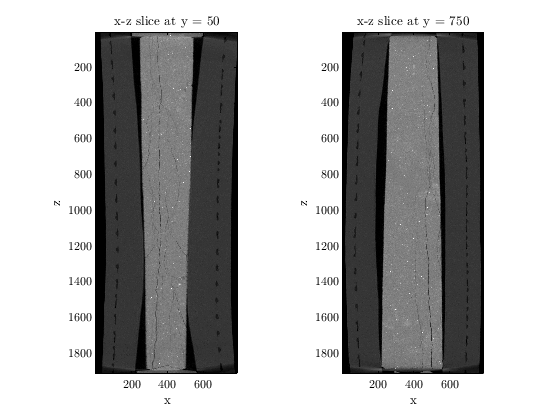

subplot(1,2,1);
imagesc(permute(squeeze(data.image(ymin,:,:)),[2 1]));
colormap('gray');
xlabel('x');
ylabel('z');
axis image
ax = gca;
ax.CLim = [10 75];
title(['x-z slice at y = ',num2str(ymin)]);

subplot(1,2,2);
imagesc(permute(squeeze(data.image(ymax,:,:)),[2 1]));
colormap('gray');
xlabel('x');
ylabel('z');
axis image
ax = gca;
ax.CLim = [10 75];
title(['x-z slice at y = ',num2str(ymax)]);

The result shown manually from the previous section indices that the initiation of the fractures spans the slices specified below

[subimageX, subimageY, subimageZ, subimage] = subvolume(data.image,[xmin,xmax,ymin,ymax,zmin,zmax]);

Visualizing the subvolume chosen

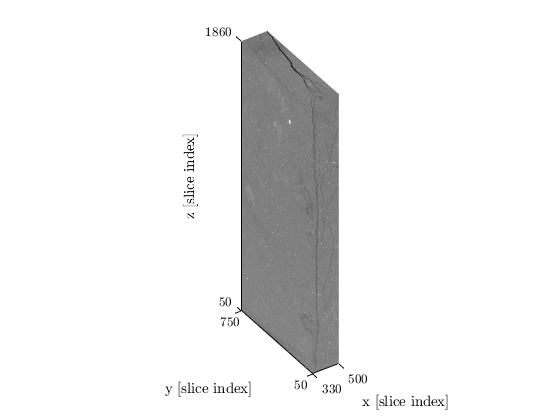

figure
s = slice(subimageX, subimageY, subimageZ,subimage,[xmin xmax],[ymin ymax],[zmin zmax]);
% s.EdgeAlpha = 0.5;
shading flat;
axis image;
colormap gray;
xlabel('x [slice index]');
xticks([xmin xmax]);
ylabel('y [slice index]');
yticks([ymin ymax]);
zlabel('z [slice index]');
zticks([zmin zmax]);
ax = gca;
ax.CLim = [10 75];

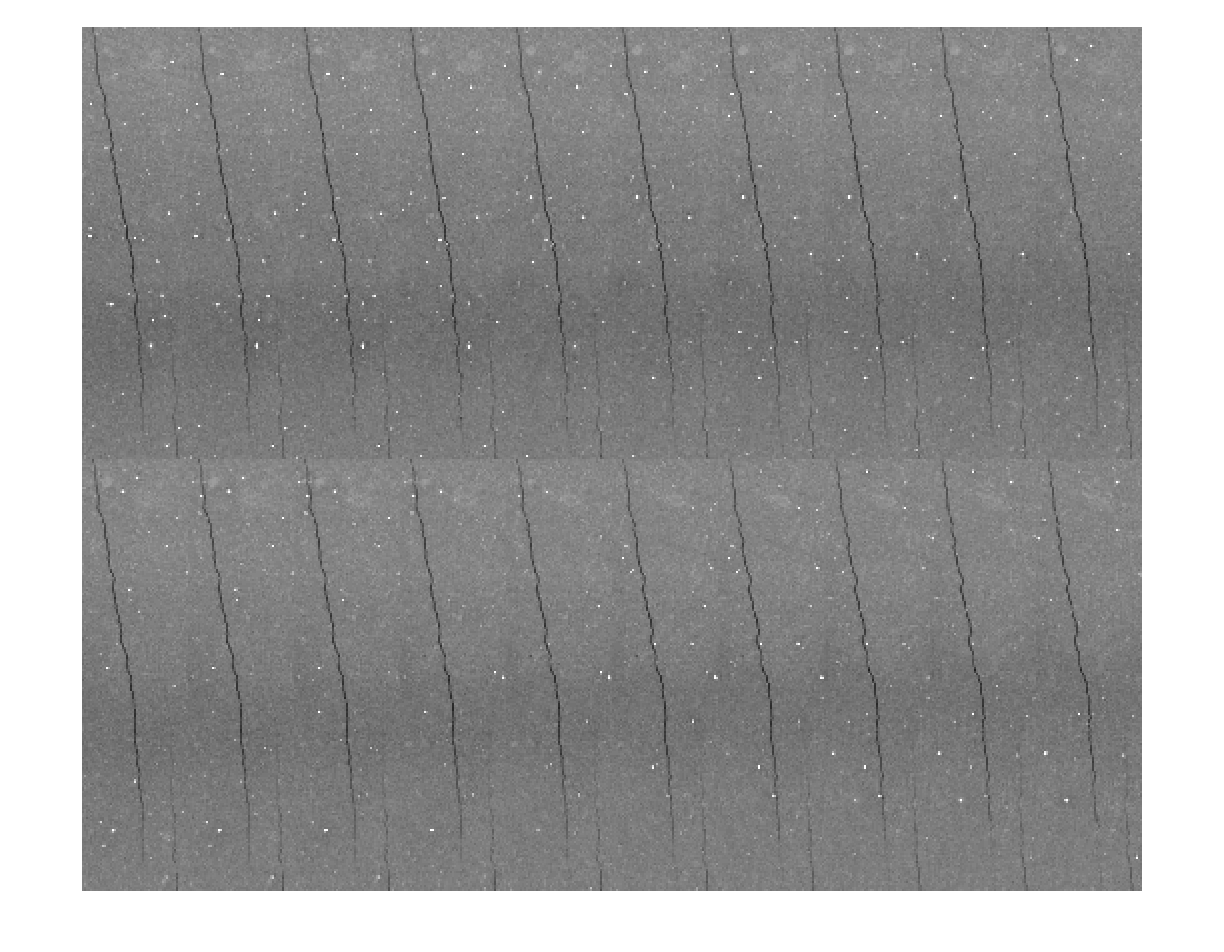

montage(subimage,'Indices',1:20,'DisplayRange',[10 75]);

subimageYZ = permute(subimage,[3 1 2]); 

Viwing some the slices along

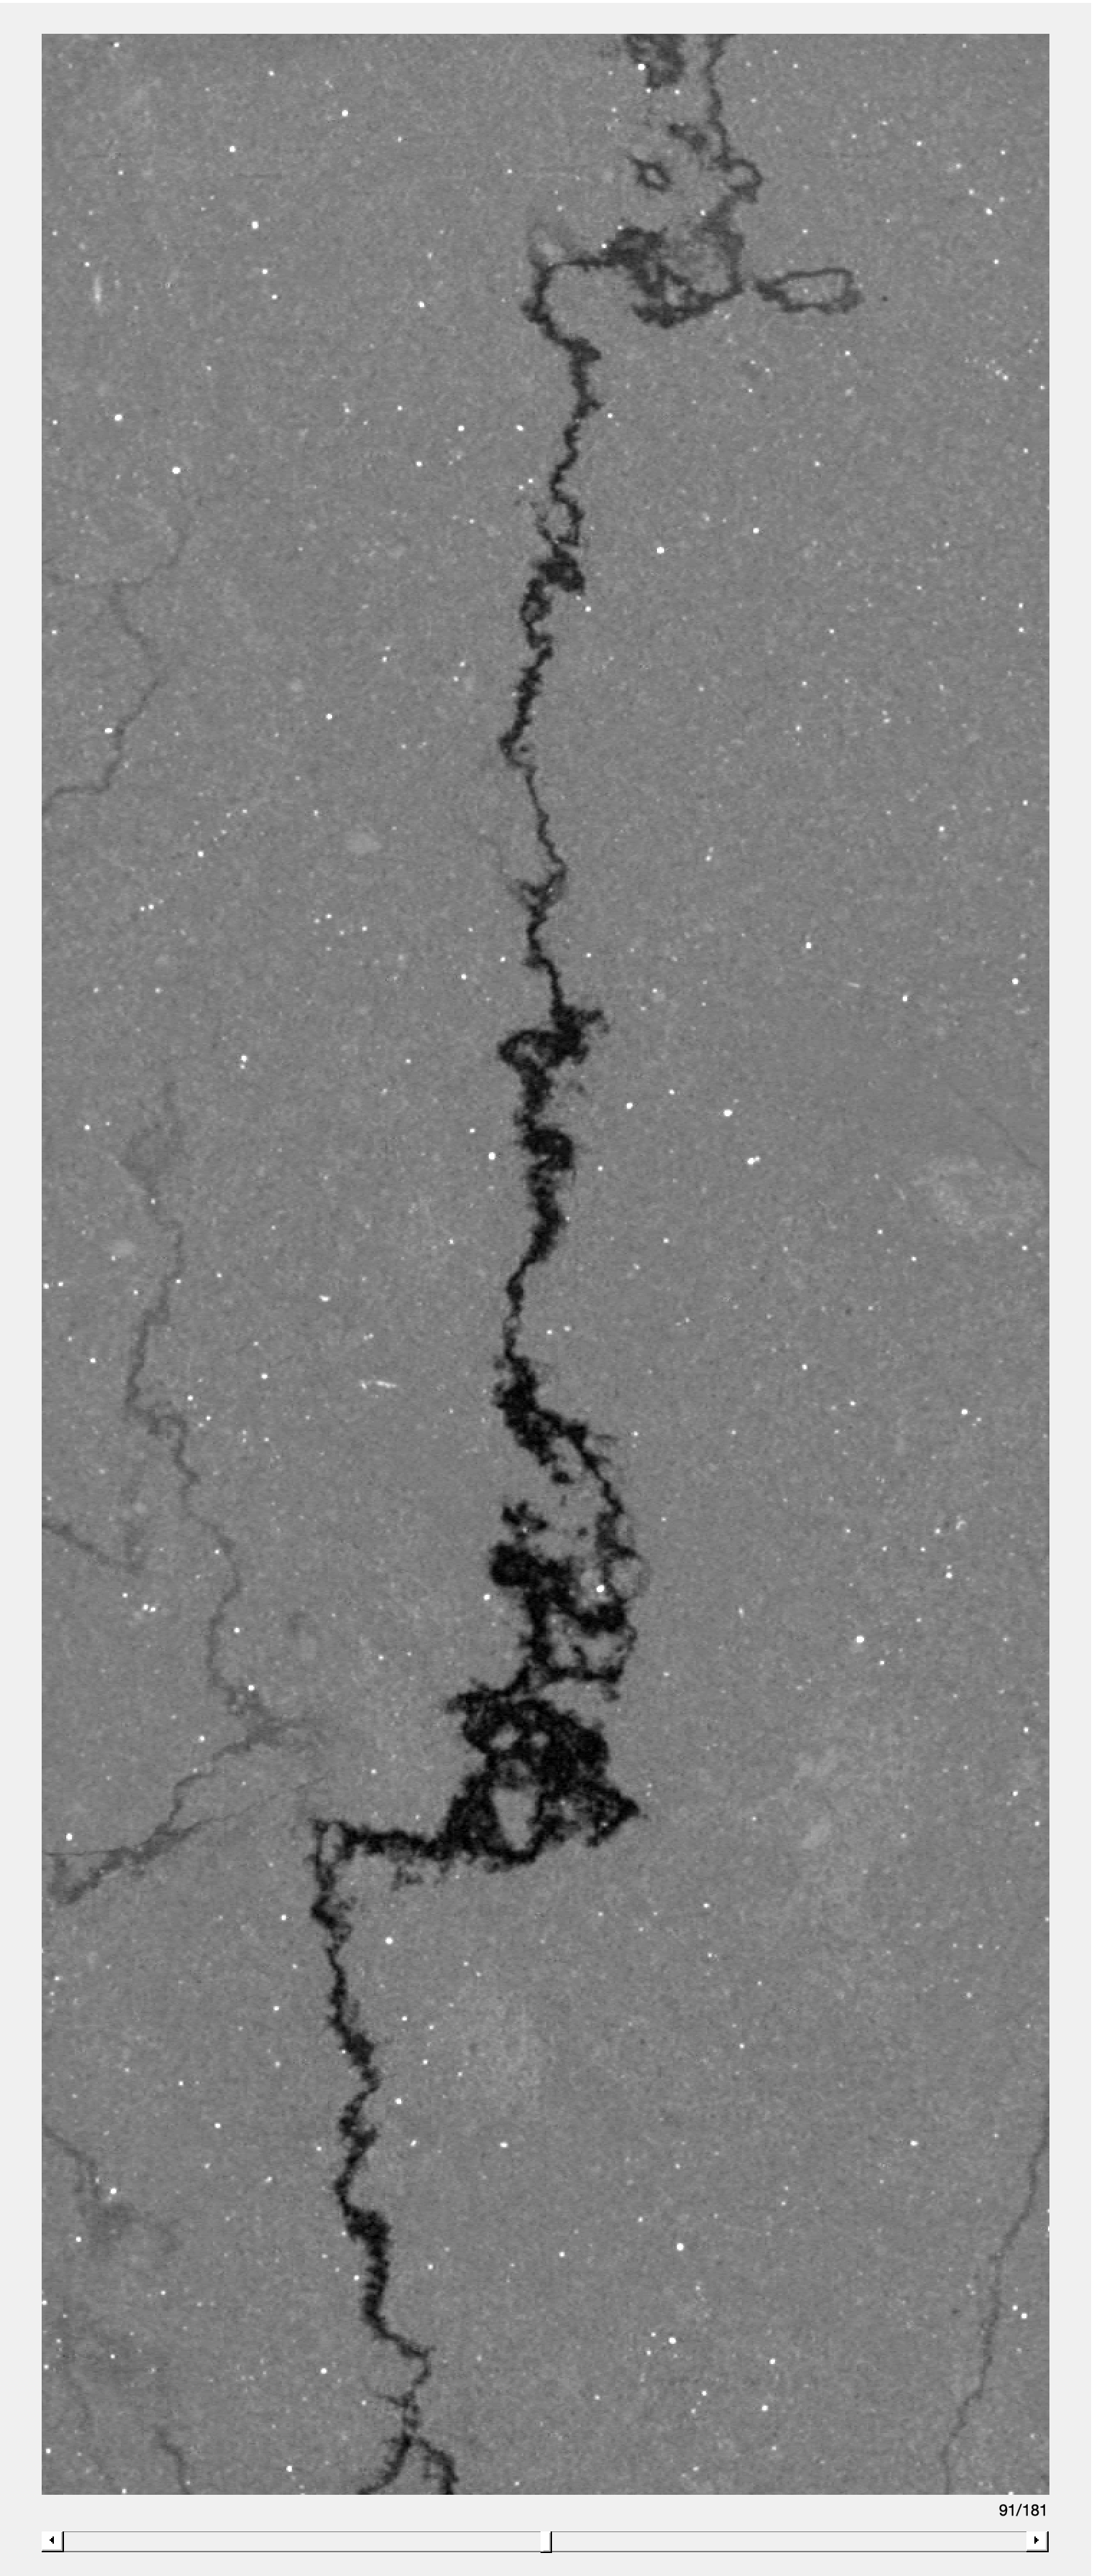

sv = sliceViewer(subimageYZ);
ax = gca;
ax.CLim = [10 75];

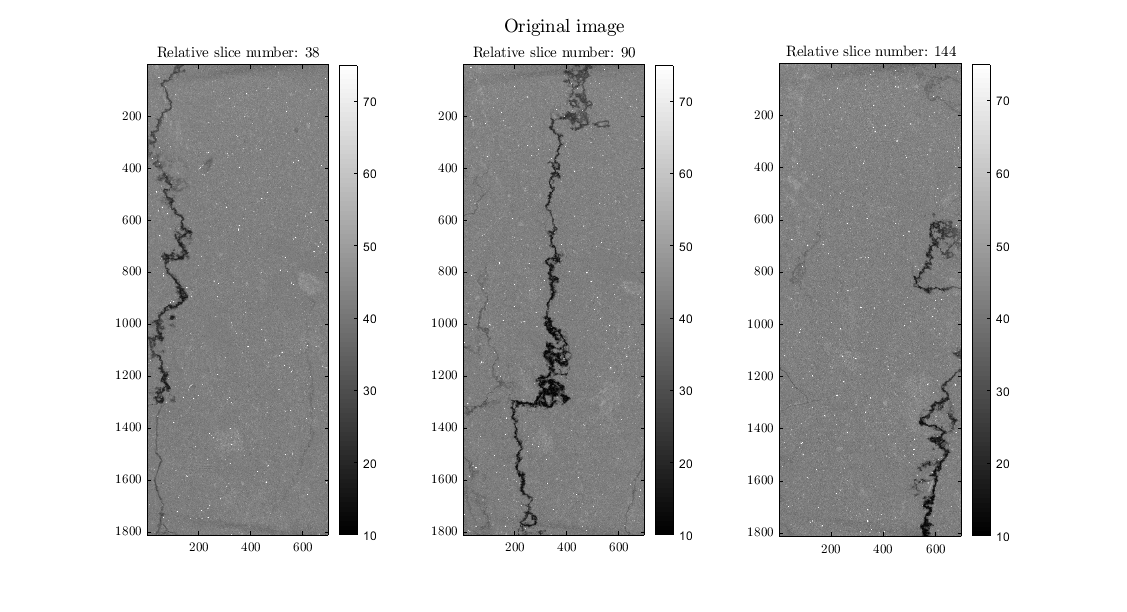

imgType = subimageYZ;
imgTypeName = 'Original';
imgCLim = [10 75];

figure('Position',[73 73 1127 612]);
subplot(1,3,1);
imagesc(imgType(:,:,38));
colormap gray;
title('Relative slice number: 38');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,2);
imagesc(imgType(:,:,90));
title('Relative slice number: 90');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,3);
imagesc(imgType(:,:,144));
title('Relative slice number: 144');
sgtitle([imgTypeName, ' image']);
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

%subimageYZComp = imcomplement(subimageYZ);

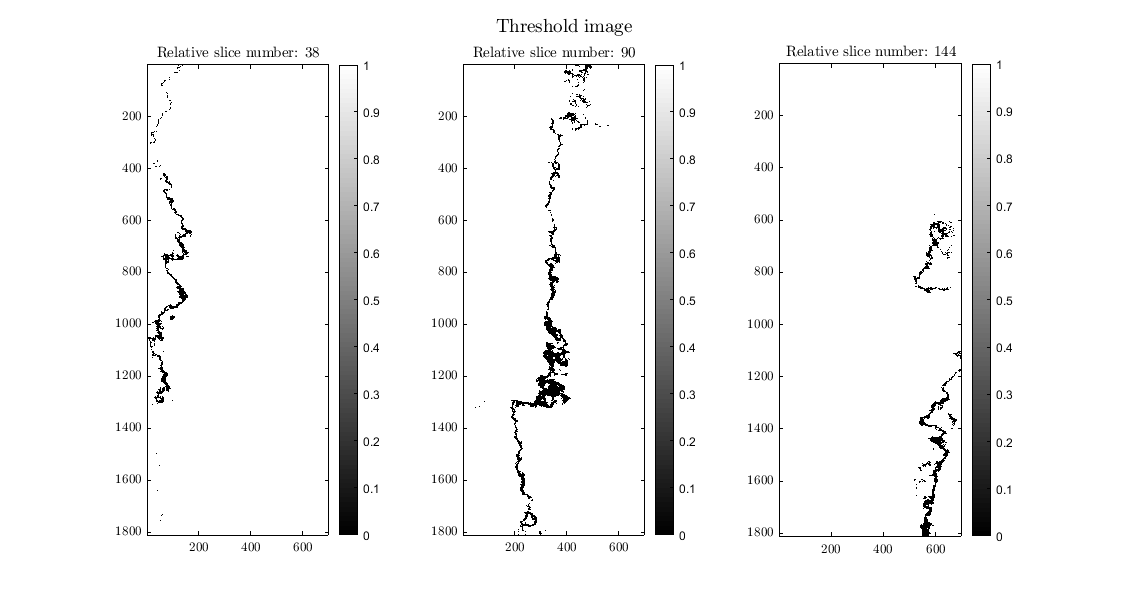

subimageYZBW = imbinarize(subimageYZ,29);

imgType = subimageYZBW;
imgTypeName = 'Threshold';
imgCLim = [0 1];

figure('Position',[73 73 1127 612]);
subplot(1,3,1);
imagesc(imgType(:,:,38));
colormap gray;
title('Relative slice number: 38');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,2);
imagesc(imgType(:,:,90));
title('Relative slice number: 90');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,3);
imagesc(imgType(:,:,144));
title('Relative slice number: 144');
sgtitle([imgTypeName, ' image']);
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

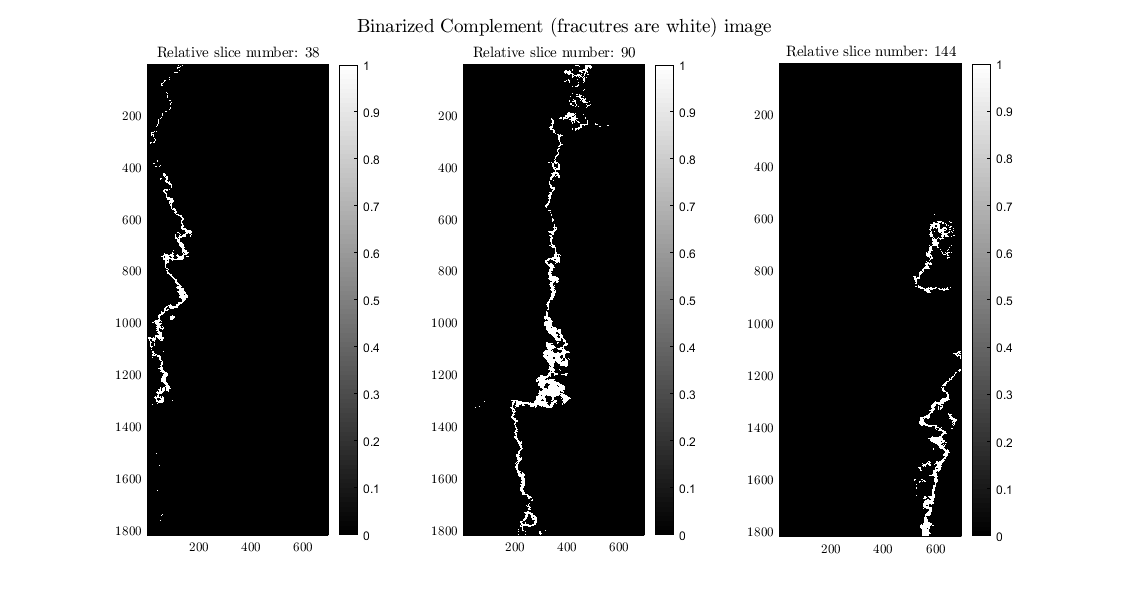

subimageYZBWComp = imcomplement(subimageYZBW);

imgType = subimageYZBWComp;
imgTypeName = 'Binarized Complement (fracutres are white)';
imgCLim = [0 1];

figure('Position',[73 73 1127 612]);
subplot(1,3,1);
imagesc(imgType(:,:,38));
colormap gray;
title('Relative slice number: 38');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,2);
imagesc(imgType(:,:,90));
title('Relative slice number: 90');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,3);
imagesc(imgType(:,:,144));
title('Relative slice number: 144');
sgtitle([imgTypeName, ' image']);
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

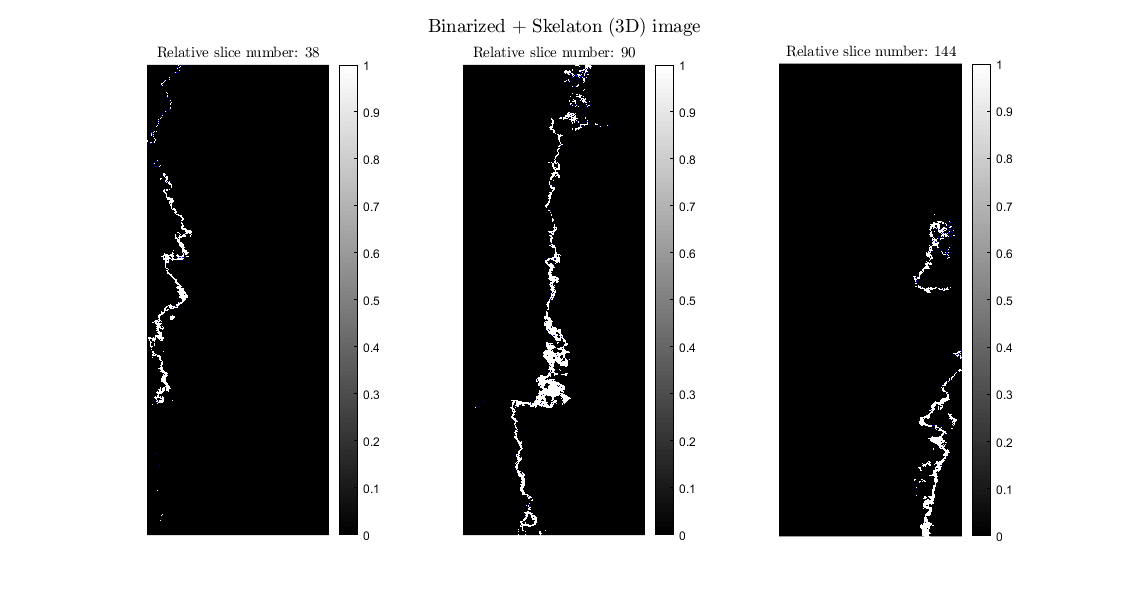

% an alternative is the regional maxima using `imregionalmax()`
subimageYZBWCompSkel = bwskel(subimageYZBWComp); 

figure

imgType = subimageYZBWComp;
imgTypeName = 'Binarized + Skelaton (3D)';
imgCLim = [0 1];

figure('Position',[73 73 1127 612]);
subplot(1,3,1);
imshow(labeloverlay(double(subimageYZBWComp(:,:,38)),subimageYZBWCompSkel(:,:,38),'Transparency',0),'InitialMagnification',100);colormap gray;
title('Relative slice number: 38');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,2);
imshow(labeloverlay(double(subimageYZBWComp(:,:,90)),subimageYZBWCompSkel(:,:,90),'Transparency',0),'InitialMagnification',100);colormap gray;
title('Relative slice number: 90');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

subplot(1,3,3);
imshow(labeloverlay(double(subimageYZBWComp(:,:,144)),subimageYZBWCompSkel(:,:,144),'Transparency',0),'InitialMagnification',100);colormap gray;
title('Relative slice number: 144');
sgtitle([imgTypeName, ' image']);
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;

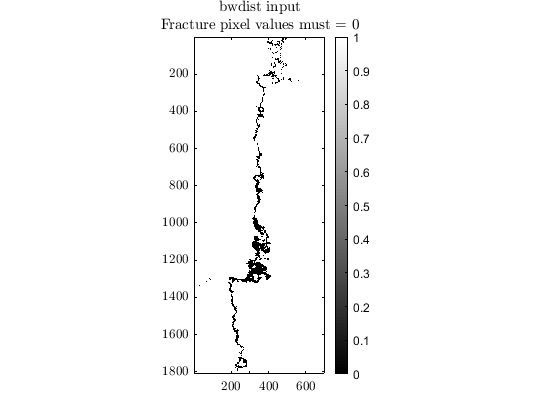

clear subimageYZBWDist;

bwdistinput = subimageYZBW;
subimageYZBWDist = bwdist(bwdistinput); % the value of the fracture pixels has to be 0 or False;

figure
imagesc(double(bwdistinput(:,:,90)));
shading flat
axis image
colormap gray
colorbar
title({'bwdist input';'Fracture pixel values must = 0'});

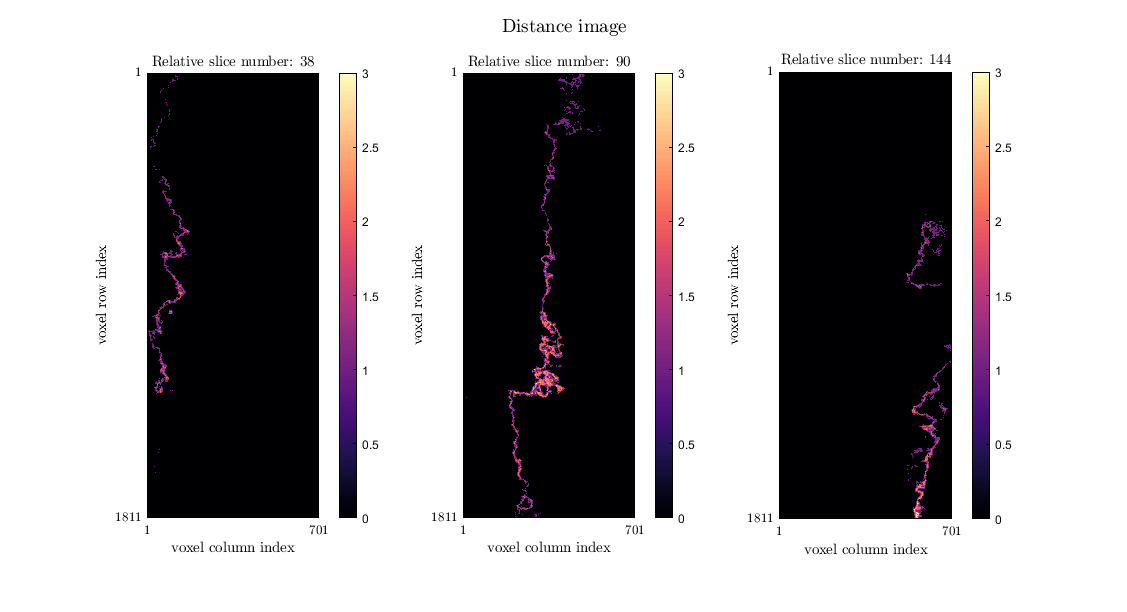

figure

imgType = subimageYZBWDist;
imgTypeName = 'Distance';
imgCLim = [0 3];

figure('Position',[73 73 1127 612]);
subplot(1,3,1);
imagesc(imgType(:,:,38));
%colormap gray;
title('Relative slice number: 38');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;
xlabel('voxel column index')
ax.XTick = [1 size(imgType,2)];
ylabel('voxel row index')
ax.YTick = [1 size(imgType,1)];

subplot(1,3,2);
imagesc(imgType(:,:,90));
title('Relative slice number: 90');
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;
xlabel('voxel column index')
ax.XTick = [1 size(imgType,2)];
ylabel('voxel row index')
ax.YTick = [1 size(imgType,1)];

subplot(1,3,3);
imagesc(imgType(:,:,144));
title('Relative slice number: 144');
sgtitle([imgTypeName, ' image']);
ax = gca;
colorbar
ax.CLim = imgCLim;
axis image;
xlabel('voxel column index')
ax.XTick = [1 size(imgType,2)];
ylabel('voxel row index')
ax.YTick = [1 size(imgType,1)];

Histogram of the aperture

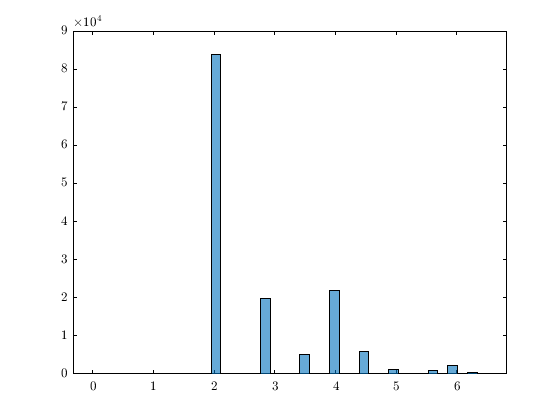

figure
histogram(subimageYZBWDist(subimageYZBWCompSkel)*2,40,'BinEdges',linspace(0,6.5,41));

nrows = size(subimageYZBWDist,1);
ncols = size(subimageYZBWDist,2);

subimageYZBWDistTargetSum = zeros(nrows,ncols);
for r = 1:nrows
    for c = 1:ncols
        subimageYZBWDistTargetSum(r,c) = sum(subimageYZBWDist(r,c,:));
    end
end

subimageYZBWDistTargetSum = subimageYZBWDistTargetSum*2;

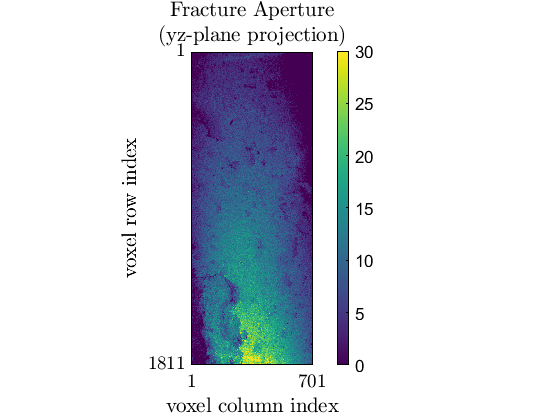

figure
imagesc(subimageYZBWDistTargetSum);
cm = InitColormaps(4);
title({'Fracture Aperture';'(yz-plane projection)'});
ax = gca;
colorbar
ax.CLim = [0 30];
axis image;
xlabel('voxel column index')
ax.XTick = [1 size(imgType,2)];
ylabel('voxel row index')
ax.YTick = [1 size(imgType,1)];
ax.FontSize = 14;

fig = gcf;
fig.PaperPosition([2 4]) = [1 10]; 

save('output/7A_fractured/7A_fractured fracture aperture dist.mat','subimageYZBWDistTargetSum','-mat');